%% =========================================================================
%% PART 1: SYSTEM INITIALIZATION & DATA ACQUISITION
%% =========================================================================
clear; clc; close all;

video_name = 'vidtest6.mp4';

if ~exist(video_name, 'file')
    error('File video "%s" tidak ditemukan. Pastikan file berada pada direktori aktif.', video_name);
end

% Inisialisasi objek VideoReader untuk membaca file video landscape
videoReader = VideoReader(video_name);

%% =========================================================================
%% PART 2: GEOMETRIC CALIBRATION & QUADRATIC REGRESSION MODEL
%% =========================================================================
% Matriks data referensi hasil pra-kalibrasi geometri di lapangan koridor
jarak_aktual = [1.5, 3.5, 4.5, 5.5, 7.0, 8.0]; % Satuan meter (Ground Truth)
H_lapangan   = [500, 400, 320, 250, 225, 220]; % Satuan piksel (px)

% Menghitung koefisien kurva regresi polinomial derajat 2 berbasis invers tinggi (1/H)
koefisien = polyfit(1./H_lapangan, jarak_aktual, 2);
coeff_a = koefisien(1); % Koefisien Kuadratik
coeff_b = koefisien(2); % Koefisien Linear
coeff_c = koefisien(3); % Konstanta Intersep sumbu Y

%% =========================================================================
%% PART 3: THRESHOLD CONFIGURATION & FILTER SETTINGS
%% =========================================================================
% Batas ambang rasio uji intensitas untuk penyaringan bayangan lantai
shadow_min = 0.55;
shadow_max = 0.92;          

% Parameter filter spasial objek dan kestabilan temporal
min_area_threshold = 1200;  % Luas minimum biner objek (mereduksi noise)
filter_size = 10;           % Panjang window memory moving average filter

% Inisialisasi variabel buffer history penyimpan data tinggi
tinggi_history = [];
frame_counter = 0;

%% =========================================================================
%% PART 4: IMAGE PREPROCESSING & BACKGROUND EXTRACTION
%% =========================================================================
% Ekstraksi frame pertama saat kondisi koridor kosong (Durasi 0-3 detik awal)
if hasFrame(videoReader)
    bgFrame = readFrame(videoReader);
    bgGray = double(rgb2gray(bgFrame)); % Konversi ke grayscale skala double
else
    error('File video kosong atau mengalami kerusakan struktur data.');
end

% Mengembalikan pointer video ke frame awal untuk masuk ke looping utama
videoReader.CurrentTime = 0;

%% =========================================================================
%% PART 5: GRAPHICAL USER INTERFACE (GUI) VIEWPORT INITIALIZATION
%% =========================================================================
hFig = figure('Name', 'Sistem Smart Surveillance - Native Landscape', 'NumberTitle', 'off');
hAx = axes('Parent', hFig);

% Mengunci dimensi resolusi video asli landscape
imgHeight = videoReader.Height;
imgWidth = videoReader.Width;

% Alokasi matriks hitam awal pada layar display grafik
hImage = imshow(zeros(imgHeight, imgWidth, 3, 'uint8'), 'Parent', hAx);
hold(hAx, 'on');

% Inisialisasi grafik komponen visual Bounding Box (Kuning) dan Teks Informasi
hRect = rectangle('Parent', hAx, 'Position', [0 0 0 0], 'EdgeColor', 'y', 'LineWidth', 2.5, 'Visible', 'off');
hText = text('Parent', hAx, 'Position', [0 0], 'String', '', 'Color', 'y', ...
    'FontSize', 13, 'FontWeight', 'bold', 'HorizontalAlignment', 'center', 'Visible', 'off');

fprintf('\n==== LOG KALIBRASI PIKSEL AKTIF DERAJAT 2 ====\n');


==== LOG KALIBRASI PIKSEL AKTIF DERAJAT 2 ====


%% =========================================================================
%% PART 6: MAIN LOOP - TEMPORAL PROCESSING & BACKGROUND SUBTRACTION
%% =========================================================================
while hasFrame(videoReader) && isvalid(hFig)
    frame = readFrame(videoReader);
    frame_counter = frame_counter + 1;

    % Konversi matriks warna aktif berjalan ke bentuk grayscale double
    grayFrame = double(rgb2gray(frame));

    % Perhitungan selisih absolut intensitas piksel (Gerakan Objek)
    diffFrame = abs(grayFrame - bgGray);
    binFrame = diffFrame > 35;

    %% =========================================================================
    %% PART 7: SHADOW REMOVAL & MORPHOLOGICAL IMAGE FILTERING
    %% =========================================================================
    % Eksekusi Brightness Ratio Test untuk eliminasi piksel bayangan lantai
    ratioFrame = grayFrame ./ (bgGray + eps);
    is_shadow = (ratioFrame >= shadow_min) & (ratioFrame <= shadow_max) & binFrame;
    binFrame(is_shadow) = 0; % Potong bayangan menjadi latar belakang hitam

    % Rangkaian Filter Operasi Morfologi (Dilasi -> Fill Holes -> Erosi)
    se = strel('disk', 7); 
    binFrame = imdilate(binFrame, se);
    binFrame = imfill(binFrame, 'holes');
    binFrame = imerode(binFrame, strel('disk', 3));

    %% =========================================================================
    %% PART 8: FEATURE EXTRACTION & MOVING AVERAGE STABILIZER
    %% =========================================================================
    % Ekstraksi data komponen geometri terhubung (Blob terbesar)
    stats = regionprops(binFrame, 'BoundingBox', 'Area');

    % Inisialisasi efek fokus visual IRIS Lab (Latar belakang diredupkan 25%)
    displayFrame = uint8(double(frame) * 0.25);

    is_detected = false;
    if ~isempty(stats)
        [maxArea, maxIdx] = max([stats.Area]);

        if maxArea > min_area_threshold
            bbox = stats(maxIdx).BoundingBox;
            tinggi_mentah = bbox(4); % Mengambil parameter tinggi vertikal kotak

            % Eksekusi Moving Average Filter untuk penstabilan temporal data
            tinggi_history = [tinggi_history, tinggi_mentah];
            if length(tinggi_history) > filter_size
                tinggi_history(1) = []; 
            end
            tinggi_stabil = mean(tinggi_history);

            %% =========================================================================
            %% PART 9: QUADRATIC DEPTH ESTIMATION & ANTI-CLIPPING METADATA
            %% =========================================================================
            % === KALKULASI FORMULA ESTIMASI JARAK POLINOMIAL DERAJAT 2 ===
            inv_H = 1 / tinggi_stabil;
            estimasi_jarak = (coeff_a * (inv_H^2)) + (coeff_b * inv_H) + coeff_c;
            if estimasi_jarak < 0; estimasi_jarak = 0; end

            % Tampilkan pembaruan log data ke Command Window per 15 frame
            if mod(frame_counter, 15) == 0
                fprintf('Frame: %4d | H-Asli: %.0f px | H-Stabil: %.0f px | Est. Jarak: %.2f m\n', ...
                    frame_counter, tinggi_mentah, tinggi_stabil, estimasi_jarak);
            end

            % Penyusunan metadata teks string label monitoring
            label_teks = sprintf('Est. Depth: %.2f m\nH-Stabil: %.0f px\nH-Asli: %.0f px', ...
                estimasi_jarak, tinggi_stabil, tinggi_mentah);

            % Proteksi koordinat teks melayang dari pemotongan batas atas (Anti-Clipping)
            text_x = bbox(1) + (bbox(3) / 2);
            text_y = bbox(2) - 30;
            if text_y < 1
                text_y = bbox(2) + 30;
            end

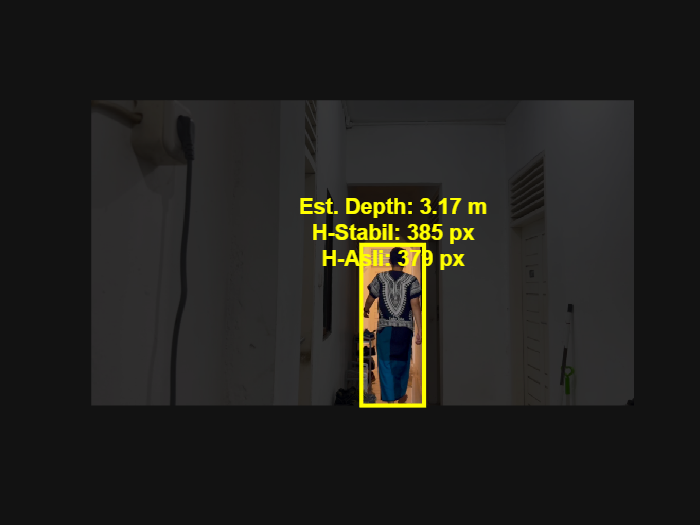

Frame:   45 | H-Asli: 229 px | H-Stabil: 213 px | Est. Jarak: 7.76 m
Frame:   60 | H-Asli: 272 px | H-Stabil: 253 px | Est. Jarak: 6.11 m
Frame:   75 | H-Asli: 332 px | H-Stabil: 315 px | Est. Jarak: 4.43 m
Frame:   90 | H-Asli: 350 px | H-Stabil: 345 px | Est. Jarak: 3.82 m
Frame:  105 | H-Asli: 358 px | H-Stabil: 355 px | Est. Jarak: 3.65 m
Frame:  120 | H-Asli: 366 px | H-Stabil: 364 px | Est. Jarak: 3.50 m
Frame:  135 | H-Asli: 376 px | H-Stabil: 374 px | Est. Jarak: 3.33 m
Frame:  150 | H-Asli: 389 px | H-Stabil: 387 px | Est. Jarak: 3.14 m
Frame:  165 | H-Asli: 405 px | H-Stabil: 402 px | Est. Jarak: 2.93 m
Frame:  180 | H-Asli: 428 px | H-Stabil: 422 px | Est. Jarak: 2.68 m
Frame:  195 | H-Asli: 457 px | H-Stabil: 448 px | Est. Jarak: 2.37 m
Frame:  210 | H-Asli: 506 px | H-Stabil: 478 px | Est. Jarak: 2.08 m
Frame:  225 | H-Asli: 572 px | H-Stabil: 551 px | Est. Jarak: 1.47 m
Frame:  240 | H-Asli: 638 px | H-Stabil: 606 px | Est. Jarak: 1.12 m
Frame:  255 | H-Asli: 644 px | H-S

            %% =========================================================================
            %% PART 10: RENDER IRIS LAB STYLE FOCUS & DISPLAY REFRESH
            %% =========================================================================
            % Mengembalikan kecerahan area tubuh manusia asli kembali 100% terang
            x1 = max(1, floor(bbox(1)));
            y1 = max(1, floor(bbox(2)));
            x2 = min(imgWidth, floor(bbox(1) + bbox(3)));
            y2 = min(imgHeight, floor(bbox(2) + bbox(4)));
            displayFrame(y1:y2, x1:x2, :) = frame(y1:y2, x1:x2, :);

            % Refresh visualisasi komponen bounding box & teks overlay
            if isvalid(hFig)
                set(hRect, 'Position', bbox, 'Visible', 'on');
                set(hText, 'Position', [text_x, text_y], 'String', label_teks, 'Visible', 'on');
            end
            is_detected = true;
        end
    end

    % Update matriks gambar display ke layar monitor utama
    if isvalid(hFig)
        set(hImage, 'CData', displayFrame);
        drawnow;
    end

    % Turn-off bounding box jika objek hilang dari area pantauan
    if ~is_detected && isvalid(hFig)
        set(hRect, 'Visible', 'off');
        set(hText, 'Visible', 'off');
        if ~isempty(tinggi_history)
            tinggi_history(1) = []; 
        end
    end

    % Sinkronisasi jeda waktu putar berdasarkan Frame Rate asli video
    pause(1/videoReader.FrameRate);
end


fprintf('\n==== Proses Analisis Video Selesai Tanpa Hambatan Eksekusi ====\n');


==== Proses Analisis Video Selesai Tanpa Hambatan Eksekusi ====
